# TE: Setup of Network Congestion Game

**Description**: Code to produce numerical example in Section VI of [1].

**Outputs**: Congestion game model saved to './output'.

**Assumptions and limitations**: none

**Other m-files required**: Files in './utils' and './functions'.

**MAT-files required**: Data in ''./data'.

**Toolboxes required**: Included in './lib' Adaptive Robust Numerical Differentiation [2],  K-Shortest Path- Yen's algorithm [3].

**Authors**: Leonardo Pedroso, Andrea Agazzi, W.P.M.H. (Maurice) Heemels, Mauro Salazar

**Revision history**:

- 18/03/2026 - First draft of full implementation (Leonardo Pedroso)

**References**:

[1] L. Pedroso, A. Agazzi, W. P. M. H. Heemels, and M. Salazar, “Token Economy for Fair and Efficient Dynamic Resource Allocation in Congestion Games,” 2026, (submitted).

[2] John D'Errico (2026). Adaptive Robust Numerical Differentiation (https://nl.mathworks.com/matlabcentral/fileexchange/13490-adaptive-robust-numerical-differentiation), MATLAB Central File Exchange.

[3] Meral Sh. (2026). K-Shortest Path- Yen's algorithm (https://nl.mathworks.com/matlabcentral/fileexchange/32513-k-shortest-path-yen-s-algorithm), MATLAB Central File Exchange.

## Initialization

% Initialize
clear;
close all;
epsl = 1e-6;
verbose = true;
load_optimal_aggregate = true;
load_initial_guess = true;

% Seed list (-1 for random seed)
% Parallel network:
%   R = 4: 32281
rng_seed = -1;

% Add functions to path
addpath(genpath(fullfile(pwd, 'lib')));
addpath(genpath(fullfile(pwd, 'utils')));
addpath(genpath(fullfile(pwd, 'functions')));

% Colorblind-safe color palette (Wong, B. Points of view: Color blindness.
% Nat Methods 8,441 (2011). https://doi.org/10.1038/nmeth.1618)
color.black = [0 0 0]/255;
color.orange = [230 159 0]/255;
color.cyan = [86 180 233]/255;
color.green = [0 158 115]/255;
color.yellow = [240 228 66]/255;
color.blue = [0 114 178]/255;
color.red = [213 94 0]/255;
color.pink = [204 121 167]/255;

% Random number seed:
if rng_seed < 0
    rng("shuffle");
    rng_seed = round(1e5*rand());
end
rng(rng_seed);
if verbose
    rng_seed
end

rng_seed = 47932

## Load network

% Load network struct
% Fields:
% - Nnodes
% - Nedges
% - edgeList
% - graph
% - nodePos
% - edgeCapacity
% - edgeLength
% - edgeFFTime
% - demand

% % Choose network

% -- Sioux Falls --
network = loadSiouxFalls();
output_folder = "output/SiouxFalls/";

% -- Illustrative --
% network = loadIllustrative();
% output_folder = "output/Illustrative/";

% -- Parallel --
% network = loadParallel(4,400);
% output_folder = "output/Parallel/";
% flag_network_is_parallel = true;
% 
% % Plot network
% figure('Position', 4*[0 0 192 144]);
% hold on;
% box on;
% ax = gca;
% ax.FontSize = 20;
% ax.TickLabelInterpreter = 'latex';
% ax.XColor = [0.3 0.3 0.3];
% ax.YColor = [0.3 0.3 0.3];
% h = plot(network.graph, ...
%     'XData', network.nodePos(:,1), ...
%     'YData', network.nodePos(:,2), ...
%     'ArrowSize', 5, ...
%     'LineWidth', 1, ...
%     'NodeColor', color.blue, ...        
%     'NodeLabelColor', color.black, ...             
%     'MarkerSize', 5, ...
%     'EdgeColor', [0.3 0.3 0.3], ...           
%     'EdgeAlpha', 0.8,...
%     'EdgeLabel', 1:network.Nedges);
%     %'NodeLabel', {});                          
% xticks([])
% yticks([])
% axis equal;
% axis tight;
% hold off;

## Model Setup: Finite Population

% Population
N = round(sum(network.demand(:,3))); % Number of agents
C = size(network.demand,1); % Number of classes (OD pairs)
mc = round(network.demand(:,3))/N; % Proportion of classes
Nc = round(mc*N); % Number of agents in each class
if verbose
    fprintf("Number of agents: %d\n", N);
    fprintf("Number of classes: %d\n", C);
end

Number of agents: 20100


Number of classes: 117



% Time
Rd = 1; % Action clock rates
Rn = 0.05; % Noise clock rates 
Rr = 0.1; % Revision clock rates

% Resources
R = network.Nedges; % Number of edges
empty_recource_included = false;

% Actions
action_max_paths = 10;
A = zeros(C,1);
Ac = cell(C,1);

% Compute set of actions for each class
if ~exist('flag_network_is_parallel', 'var') || ~flag_network_is_parallel
    aux = full(adjacency(network.graph, 'weighted'));
    aux(aux == 0) = inf;
    for c = 1:C
        [paths,~] = kShortestPath(aux, network.demand(c,1), network.demand(c,2), action_max_paths);
        Ac{c} = cell(length(paths),1);
        for p_idx = 1:length(paths)
            Ac{c}{p_idx} = zeros(length(paths{p_idx})-1,1);
            for r = 1:length(paths{p_idx})-1
                Ac{c}{p_idx}(r) = findedge(network.graph, paths{p_idx}(r), paths{p_idx}(r+1));
            end
        end
        A(c) = length(paths);
    end
end
if exist('flag_network_is_parallel', 'var') && flag_network_is_parallel
    for c = 1:C
        Ac{c} = cell(R,1);
        for r = 1:R
            Ac{c}{r} = [r];
        end
        A(c) = R;
    end
end
if verbose
    c = 1;
    fprintf("Class: %d\n",c);
    fprintf("\tOrigin: %d\n",network.demand(c,1));
    fprintf("\tDestination: %d\n",network.demand(c,2));
    fprintf("\tNumber of actions: %d\n",A(c));
    for a = 1:A(c), fprintf("\t\tAction %d: %s\n", a, mat2str(Ac{c}{a})); end
    if C > 1
        c = 2;
        fprintf("Class: %d\n",c);
        fprintf("\tOrigin: %d\n",network.demand(c,1));
        fprintf("\tDestination: %d\n",network.demand(c,2));
        fprintf("\tNumber of actions: %d\n",A(c));
        for a = 1:A(c), fprintf("\t\tAction %d: %s\n", a, mat2str(Ac{c}{a})); end
    end
end

Class: 1


	Origin: 10


	Destination: 1


	Number of actions: 10


		Action 1: [26;23;11;8;5]
		Action 2: [27;31;8;5]
		Action 3: [27;33;35;5]
		Action 4: [29;47;19;14;3]
		Action 5: [26;23;12;14;3]
		Action 6: [29;50;54;17;19;14;3]
		Action 7: [29;47;19;15;11;8;5]
		Action 8: [26;24;19;14;3]
		Action 9: [27;31;9;12;14;3]
		Action 10: [30;52;47;19;14;3]


Class: 2


	Origin: 10


	Destination: 4


	Number of actions: 10


		Action 1: [26;23;11]
		Action 2: [27;31]
		Action 3: [29;47;19;15;11]
		Action 4: [27;33;35;6]
		Action 5: [29;50;54;17;19;15;11]
		Action 6: [26;24;19;15;11]
		Action 7: [28;44;40;31]
		Action 8: [30;52;47;19;15;11]
		Action 9: [29;47;21;23;11]
		Action 10: [29;49;53;57;44;40;31]


if verbose
    fprintf("Number of resources: %d\n", R);
    fprintf("Total number of actions: %d\n", sum(A));
end

Number of resources: 76


Total number of actions: 1170


% Agent states
k_max = 100;
K = (0:1:k_max)';

% Resource latencies
lr = cell(R,1);
for r = 1:R
    lr{r} = @(sigma) network.edgeFFTime(r)*(1+0.15*(sigma*N/network.edgeCapacity(r))^4);
end

## Aggregate optimum

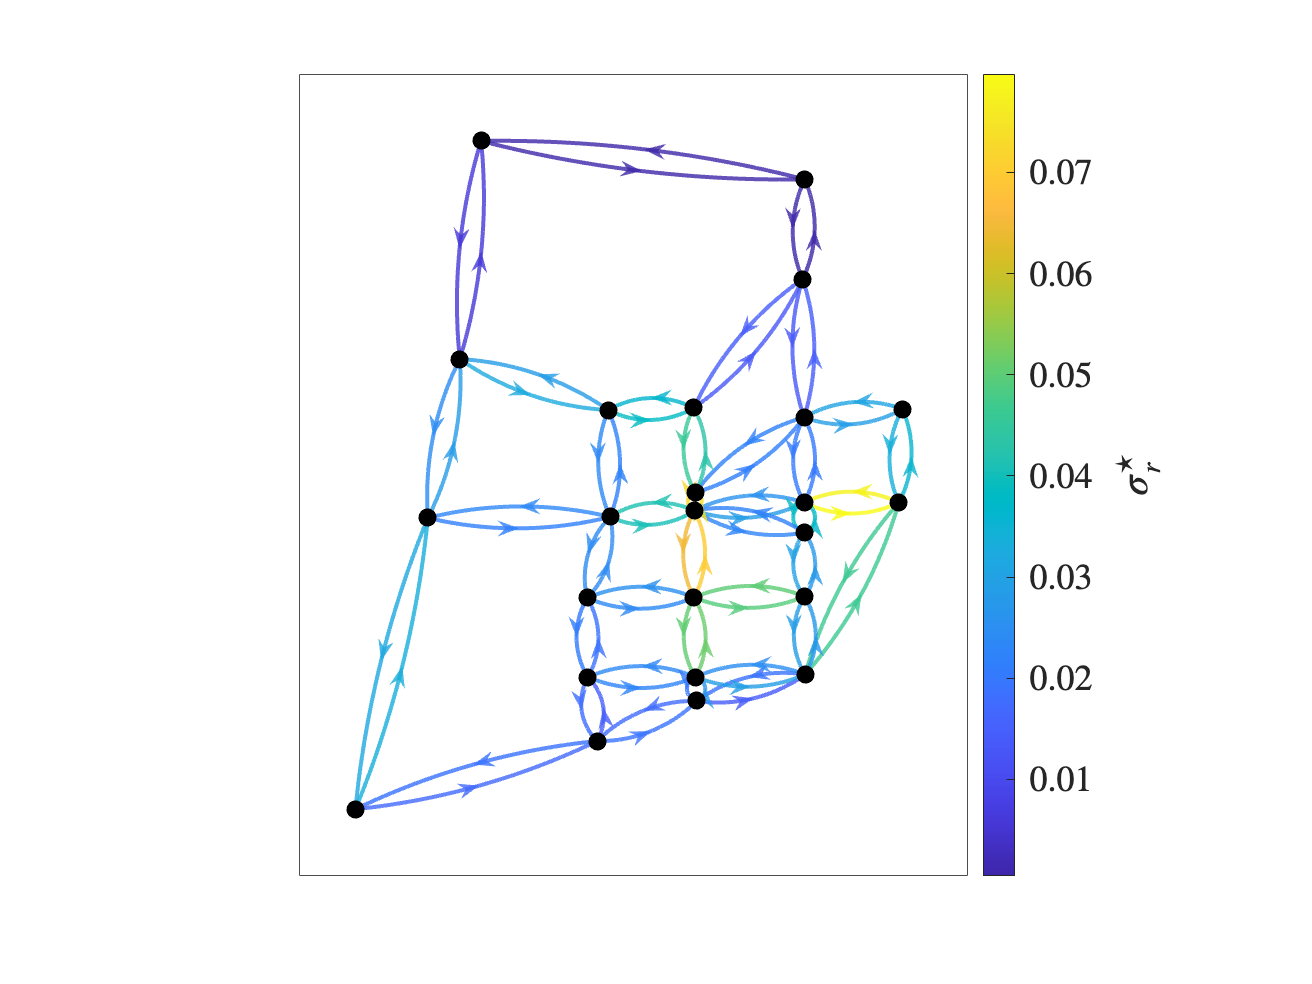

% Objective
J_eff = @(sigma_a) J_eff_wrapper(sigma_a,C,R,A,Ac,lr);
J_eff_sigma_r = @(sigma_r) J_eff_sigma_r_wrapper(sigma_r,C,R,A,Ac,lr);
J_F = @(sigma_a) J_F_wrapper(sigma_a,C,R,A,Ac,lr);

J = @(sigma_a) -J_F(sigma_a) - 0.1*J_eff(sigma_a);

% Compute (or load) aggregate optimum
if load_optimal_aggregate
    try 
        load(output_folder+'aggregate_optimum.mat','sigma_a_star','sigma_r_star','l_r_star','l_a_star','D_sigma_Jeff','w_bar_star');
    catch
        warning("No previously computed agreggate optimum was found.");
        load_optimal_aggregate = false;
    end
end
if ~load_optimal_aggregate
    % fmincon try
    % Positivity constraint
    A_ineq = -eye(sum(A));
    b_ineq = zeros(sum(A),1);
    % Equality constraint (matching demand)
    b_eq = mc*Rd;
    A_eq = zeros(C,sum(A));
    count = 0;
    for c = 1:C
        A_eq(c,count+1:count+A(c)) = ones(1,A(c));
        count = count + A(c);
    end
    
    % Initial guess
    if load_initial_guess
        try 
            load(output_folder+'aggregate_optimum_10_cong20_init.mat','sigma_a_star');
            sigma_a_0 = cell2mat(sigma_a_star);
            clear sigma_a_star;
        catch
            error("No initial guess was found.");
            
        end
    else
        sigma_a_0 = zeros(sum(A),1);
        count = 0;
        for c = 1:C
            sigma_a_0(count+1:count+A(c)) = Rd*mc(c)/A(c);
            count = count + A(c);
        end
    end
    
    
    % Compute optimum
    opts = optimoptions('fmincon','Display','iter','Algorithm','sqp-legacy','UseParallel',true,'MaxFunctionEvaluations',200*sum(A));
    [sigma_a_star_aux,fval,exitflag,output] = fmincon(J,sigma_a_0,A_ineq,b_ineq,A_eq,b_eq,[],[],[],opts);
    sigma_r_star = sigma_a2r(sigma_a_star_aux,C,R,A,Ac);
    %sigma_r_star'
    
    if exitflag == 1 || 2
        if exitflag == 2
            warning("Found a possibly a local minimum.");
        end
    else
        error("Unable to compute agreggate optimum.")
    end
    % Compute Jacobian
    D_sigma_Jeff = jacobianest(J_eff_sigma_r,sigma_r_star);
    
    % Compute resource latencies at the optimum
    l_r_star = zeros(R,1);
    for r = 1:R
        l_r_star(r) = lr{r}(sigma_r_star(r));
    end
    sigma_r_star'
    l_r_star'
    %sum(abs(l_r_star-mean(l_r_star)))/mean(l_r_star)

    % Compute action flows latencies at the optimum
    sigma_a_star = cell(C,1);
    count = 0;
    for c = 1:C
        sigma_a_star{c,1} = sigma_a_star_aux(count+1:count+A(c));
        count = count + A(c);
    end
    l_a_star = cell(C,1);
    count = 0;
    for c = 1:C
        l_a_star{c,1} = zeros(A(c),1);
        for a = 1:A(c)
            for r = Ac{c}{a}'
                l_a_star{c,1}(a) = l_a_star{c,1}(a) + lr{r}(sigma_r_star(r));
            end
        end
    end

    for c = 1:2
        fprintf(sprintf("Class %d:\n",c));
        sigma_a_star{c,1}'
        l_a_star{c,1}'
    end

    % Compute average payoffs at the optimum 
    w_bar_star = sigma_a2w_bar(sigma_a_star_aux,C,R,A,Ac,lr);
    w_bar_star'
 

    save(output_folder+'aggregate_optimum.mat','sigma_a_star','sigma_r_star','l_r_star','l_a_star','D_sigma_Jeff','w_bar_star');
    
end
% Plot agreggate optimal flows
cmap = parula(256);
figure('Position', 4*[0 0 192 144]);
hold on;
box on;
ax = gca;
ax.FontSize = 20;
ax.TickLabelInterpreter = 'latex';
ax.XColor = [0.3 0.3 0.3];
ax.YColor = [0.3 0.3 0.3];
h = plot(network.graph, ...
    'XData', network.nodePos(:,1), ...
    'YData', network.nodePos(:,2), ...
    'ArrowSize', 8, ...
    'LineWidth', 2, ...
    'NodeColor', color.black, ...        
    'NodeLabelColor', color.black, ...             
    'MarkerSize', 8, ...
    'EdgeCData', sigma_r_star,...
    'EdgeColor', 'flat', ...  
    'EdgeAlpha', 0.8,...
    'EdgeLabel',{},...
    'NodeLabel', {});                          
colormap(cmap);
cb = colorbar;
cb.Label.Interpreter = 'latex';
cb.Label.String = '$\sigma^{\star}_r$';
cb.Label.FontSize = 20;
cb.TickLabelInterpreter = 'latex';
xticks([])
yticks([])
axis equal;
axis tight;
hold off;
exportgraphics(gcf,'./fig/SF_optflows.pdf','ContentType', 'vector');


% Flag that model setup has been carried out
flag_setup_OK = true;